clc;
clear all;
close all;

%% Uploading Data Sets (expects columns: x, y, z, p)
Data   = xlsread('CarbonateMudstone.xlsx');   % <— your file name here

Choice = 0.70;                   % Train/Test split fraction
Np     = 11;                      % Number of input columns

%% Data Randomization (aligned with your template)
rand('seed',3100);
Length_Data  = length(Data);
Random_Nums  = randperm(Length_Data,Length_Data)';
Data_random  = Data(Random_Nums, :);

Data_Tr      = Data_random(1 : ceil(Length_Data * Choice), :);
Data_Tst     = Data_random(length(Data_Tr)+1 : end, :);

Data_Tr      = sortrows(Data_Tr,1);
Data_Tst     = sortrows(Data_Tst,1);

% Training_Depth  = Data_Tr(:,1);  % keep commented if depth plotting is needed later
% Testing_Depth   = Data_Tst(:,1);

Input_Training   = Data_Tr(:, 2 : Np+1);
Output_Training  = Data_Tr(:, Np + 2);

Input_Testing    = Data_Tst(:, 2 : Np+1);
Output_Testing   = Data_Tst(:, Np + 2);

mD = Data(:, Np+1);              % measured (real) values (whole dataset)

%% Sweep settings
neuron_range = 30:40;                     % hidden layer sizes
transfer_list = {'purelin','tansig'};    % hidden TFs to try

% Store results for ALL cases
Results = {};  % {'transfer_fn', neurons, 'AAPE_train','MSE_train','R2_train','AAPE_test','MSE_test','R2_test'}

%% Loop over transfer functions and neuron counts (keeps your training params)
for t = 1:numel(transfer_list)
    tf_name = transfer_list{t};
    for L1_Neurons = neuron_range

        % --- Create a Neural Network (single hidden layer) ---
        net  = fitnet(L1_Neurons);     % single hidden layer

        % Keep your training configuration
        net.trainFcn                = 'trainbfg';    % Levenberg-Marquardt
        net.trainParam.showWindow   = 1;            % show training GUI
        net.layers{1}.transferFcn   = tf_name;      % 'purelin' OR 'tansig'
        net.trainParam.epochs       = 1000;         % max epochs
        net.trainParam.lr           = 0.12;         % learning rate
        net.trainParam.mc           = 0.6;          % momentum
        net.trainParam.min_grad     = 0;
        net.trainParam.mu_max       = 1E100;

        % Internal divider for Train/Validation only (we already have external Test)
        net.divideParam.trainRatio  = 0.75;
        net.divideParam.valRatio    = 0.25;
        net.divideParam.testRatio   = 0.00;

        % --- Train on TRAINING set ---
        [net, tr]           = train(net, Input_Training', Output_Training');
        Results_Training    = net(Input_Training')';  % predictions (train)
        Results_Testing     = net(Input_Testing')';   % predictions (test)

        % --- Metrics (aligned with your post-processing) ---
        AAPE_Train = mean(abs((Output_Training - Results_Training)./Output_Training));
        AAPE_Test  = mean(abs((Output_Testing - Results_Testing)./Output_Testing));

        MSE_Train  = mean((Output_Training - Results_Training).^2);
        MSE_Test   = mean((Output_Testing - Results_Testing).^2);

        % R^2 like your code (uses variance of predictions)
        R_squared_training = 1 - sum((Results_Training - Output_Training).^2) ...
                                / sum((Results_Training - mean(Results_Training)).^2);
        R_squared_testing  = 1 - sum((Results_Testing  - Output_Testing ).^2) ...
                                / sum((Results_Testing  - mean(Results_Testing )).^2);

        % --- Outliers relative to global measured range (same logic as your code) ---
        max_mD = max(mD);
        min_mD = min(mD);

        count_higher_values_tr = sum(Results_Training > max_mD);
        count_lower_values_tr  = sum(Results_Training < min_mD);

        count_higher_values_ts = sum(Results_Testing > max_mD);
        count_lower_values_ts  = sum(Results_Testing < min_mD);

        % --- Log to Command Window (optional) ---
        fprintf('\n[%s] Neurons=%d\n', tf_name, L1_Neurons);
        fprintf('Train: AAPE=%.6f, MSE=%.6f, R2=%.6f | +ve=%d, -ve=%d\n', ...
            AAPE_Train, MSE_Train, R_squared_training, count_higher_values_tr, count_lower_values_tr);
        fprintf('Test : AAPE=%.6f, MSE=%.6f, R2=%.6f | +ve=%d, -ve=%d\n', ...
            AAPE_Test,  MSE_Test,  R_squared_testing,  count_higher_values_ts, count_lower_values_ts);

        % --- Collect into results table ---
        Results(end+1,:) = { ...
            tf_name, L1_Neurons, ...
            AAPE_Train, MSE_Train, R_squared_training, ...
            AAPE_Test,  MSE_Test,  R_squared_testing, ...
            count_higher_values_tr, count_lower_values_tr, ...
            count_higher_values_ts, count_lower_values_ts};
    end
end


[purelin] Neurons=30


Train: AAPE=0.323903, MSE=0.486770, R2=0.798090 | +ve=0, -ve=48


Test : AAPE=0.645594, MSE=0.573550, R2=0.788820 | +ve=0, -ve=24



[purelin] Neurons=31


Train: AAPE=0.365848, MSE=0.510097, R2=0.787604 | +ve=0, -ve=52


Test : AAPE=0.670037, MSE=0.533556, R2=0.793350 | +ve=0, -ve=23



[purelin] Neurons=32


Train: AAPE=0.344792, MSE=0.511007, R2=0.802896 | +ve=0, -ve=50


Test : AAPE=0.625800, MSE=0.487242, R2=0.824970 | +ve=0, -ve=23



[purelin] Neurons=33


Train: AAPE=0.508867, MSE=0.612455, R2=0.667498 | +ve=0, -ve=46


Test : AAPE=0.837575, MSE=0.683624, R2=0.642627 | +ve=0, -ve=22



[purelin] Neurons=34


Train: AAPE=0.443052, MSE=0.549540, R2=0.752374 | +ve=0, -ve=48


Test : AAPE=0.818438, MSE=0.646484, R2=0.727918 | +ve=0, -ve=23



[purelin] Neurons=35


Train: AAPE=0.366966, MSE=0.531883, R2=0.780231 | +ve=0, -ve=49


Test : AAPE=0.724167, MSE=0.612578, R2=0.774367 | +ve=0, -ve=23



[purelin] Neurons=36


Train: AAPE=0.339171, MSE=0.480177, R2=0.797309 | +ve=0, -ve=47


Test : AAPE=0.637401, MSE=0.557951, R2=0.793010 | +ve=0, -ve=23



[purelin] Neurons=37


Train: AAPE=0.349135, MSE=0.510619, R2=0.805604 | +ve=0, -ve=50


Test : AAPE=0.650783, MSE=0.493581, R2=0.824276 | +ve=0, -ve=23



[purelin] Neurons=38


Train: AAPE=0.218865, MSE=0.265356, R2=0.897317 | +ve=0, -ve=52


Test : AAPE=0.330373, MSE=0.296564, R2=0.903792 | +ve=0, -ve=24



[purelin] Neurons=39


Train: AAPE=0.358275, MSE=0.470459, R2=0.793716 | +ve=0, -ve=51


Test : AAPE=0.672860, MSE=0.578900, R2=0.778368 | +ve=0, -ve=24



[purelin] Neurons=40


Train: AAPE=0.230195, MSE=0.270722, R2=0.895512 | +ve=0, -ve=51


Test : AAPE=0.323979, MSE=0.304383, R2=0.901369 | +ve=0, -ve=23



[tansig] Neurons=30


Train: AAPE=0.270039, MSE=0.266828, R2=0.894740 | +ve=0, -ve=47


Test : AAPE=0.645071, MSE=0.520717, R2=0.821706 | +ve=0, -ve=23



[tansig] Neurons=31


Train: AAPE=0.205370, MSE=0.203434, R2=0.928226 | +ve=0, -ve=51


Test : AAPE=0.559842, MSE=0.414171, R2=0.881740 | +ve=0, -ve=25



[tansig] Neurons=32


Train: AAPE=0.384364, MSE=0.552833, R2=0.791793 | +ve=0, -ve=60


Test : AAPE=0.686009, MSE=0.768164, R2=0.722883 | +ve=0, -ve=27



[tansig] Neurons=33


Train: AAPE=0.267806, MSE=0.277619, R2=0.896029 | +ve=0, -ve=48


Test : AAPE=0.614171, MSE=0.451224, R2=0.859673 | +ve=0, -ve=25



[tansig] Neurons=34


Train: AAPE=0.373640, MSE=0.418275, R2=0.827165 | +ve=0, -ve=54


Test : AAPE=0.660289, MSE=0.739485, R2=0.739171 | +ve=0, -ve=26



[tansig] Neurons=35


Train: AAPE=0.468614, MSE=0.563504, R2=0.735290 | +ve=0, -ve=50


Test : AAPE=0.798878, MSE=0.676755, R2=0.688505 | +ve=0, -ve=25



[tansig] Neurons=36


Train: AAPE=0.254833, MSE=0.244746, R2=0.909212 | +ve=0, -ve=49


Test : AAPE=0.550460, MSE=0.391391, R2=0.880913 | +ve=0, -ve=23



[tansig] Neurons=37


Train: AAPE=0.243063, MSE=0.190580, R2=0.928001 | +ve=0, -ve=53


Test : AAPE=0.449935, MSE=0.349770, R2=0.886969 | +ve=0, -ve=25



[tansig] Neurons=38


Train: AAPE=0.240622, MSE=0.234644, R2=0.919657 | +ve=0, -ve=49


Test : AAPE=0.505944, MSE=0.463541, R2=0.864712 | +ve=0, -ve=23



[tansig] Neurons=39


Train: AAPE=0.334831, MSE=0.398347, R2=0.831617 | +ve=0, -ve=47


Test : AAPE=0.580219, MSE=0.558682, R2=0.791796 | +ve=0, -ve=22



[tansig] Neurons=40


Train: AAPE=0.469457, MSE=0.466838, R2=0.792169 | +ve=0, -ve=47


Test : AAPE=0.873966, MSE=0.568128, R2=0.759362 | +ve=0, -ve=23



%% Build results table and display ALL cases
T = cell2table(Results, 'VariableNames', { ...
    'transfer_fn','neurons', ...
    'AAPE_train','MSE_train','R2_train', ...
    'AAPE_test','MSE_test','R2_test', ...
    'OutliersTrain_Pos','OutliersTrain_Neg', ...
    'OutliersTest_Pos','OutliersTest_Neg'});

% Sort for readability: by transfer_fn then neurons
T = sortrows(T, {'transfer_fn','neurons'});
disp('--- ALL RESULTS ---');

--- ALL RESULTS ---


disp(T);

    transfer_fn    neurons    AAPE_train    MSE_train    R2_train    AAPE_test    MSE_test    R2_test    OutliersTrain_Pos    OutliersTrain_Neg    OutliersTest_Pos    OutliersTest_Neg
    ___________    _______    __________    _________    ________    _________    ________    _______    _________________    _________________    ________________    ________________

    {'purelin'}      30         0.3239       0.48677     0.79809      0.64559     0.57355     0.78882            0                   48                   0                   24       
    {'purelin'}      31        0.36585 

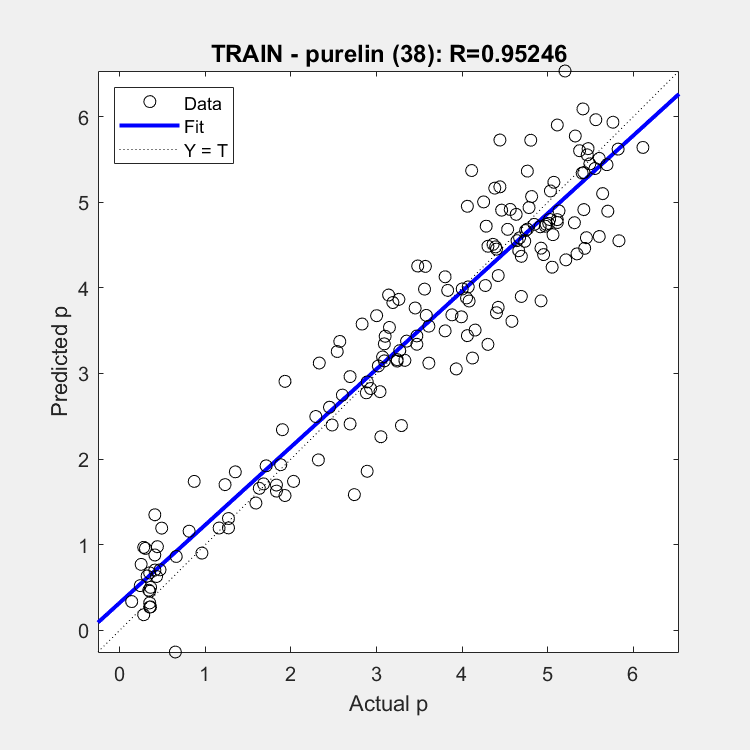

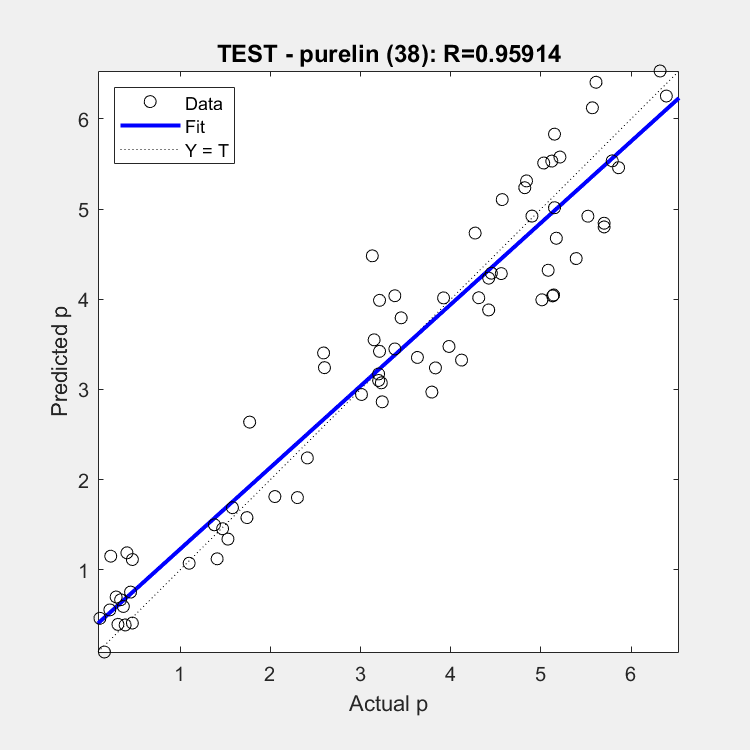

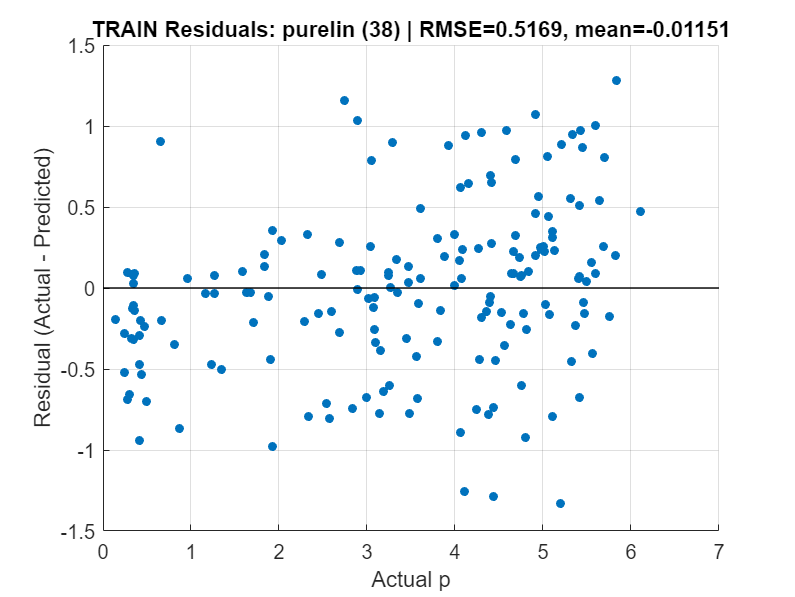

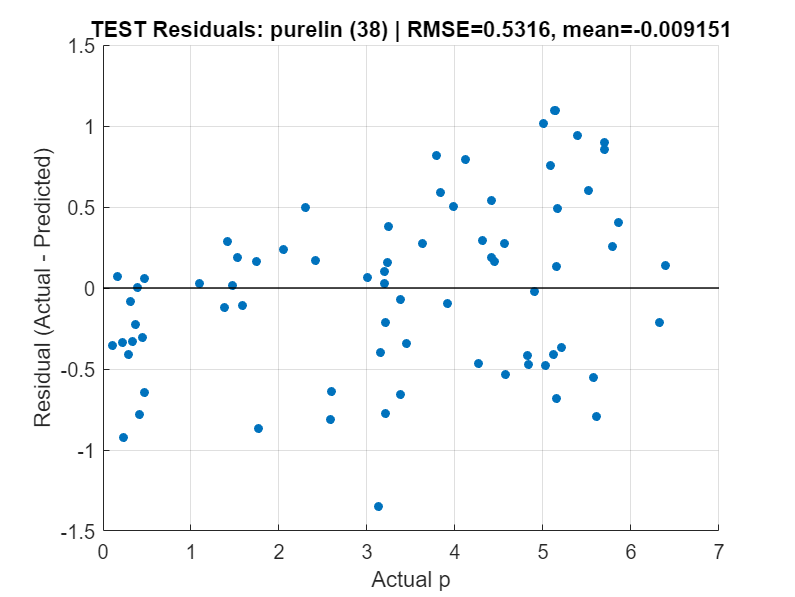

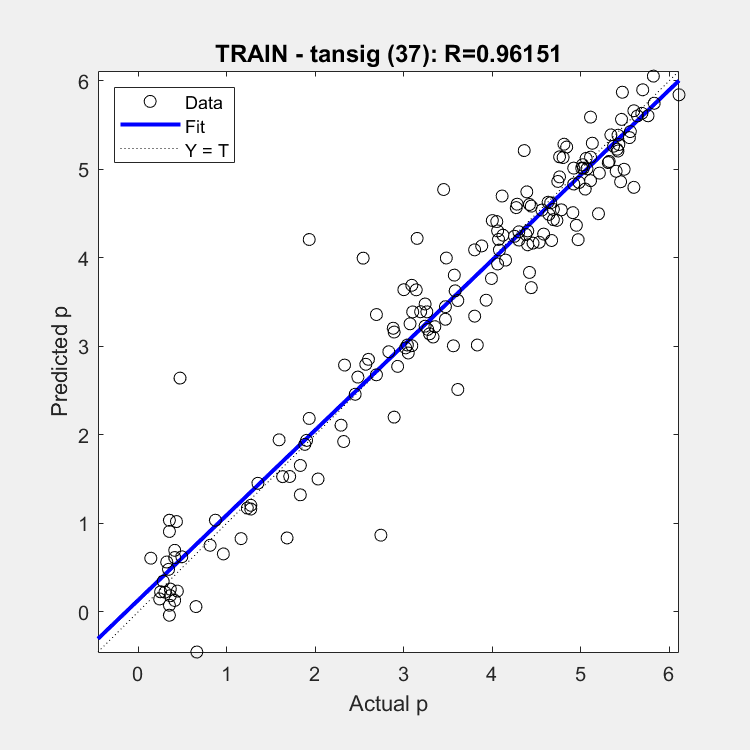

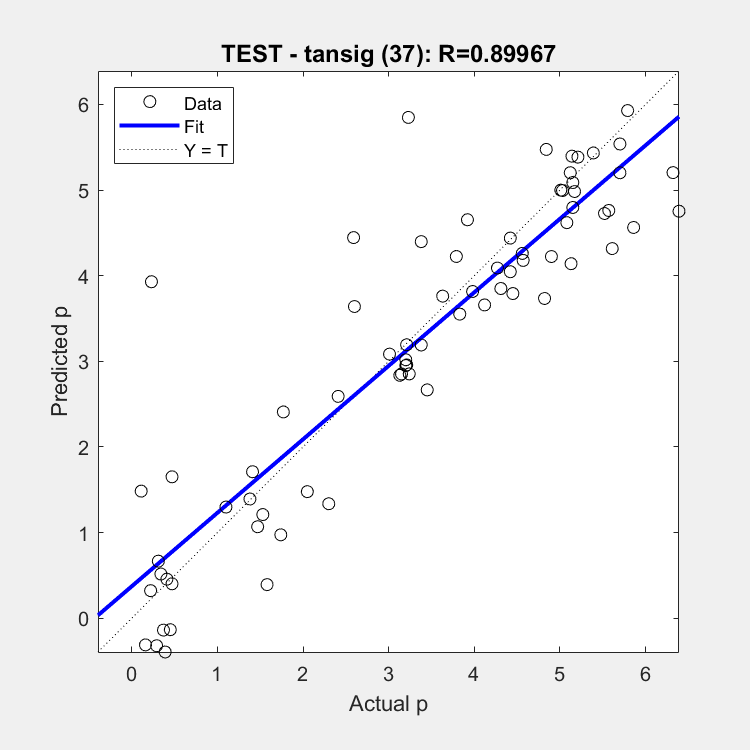

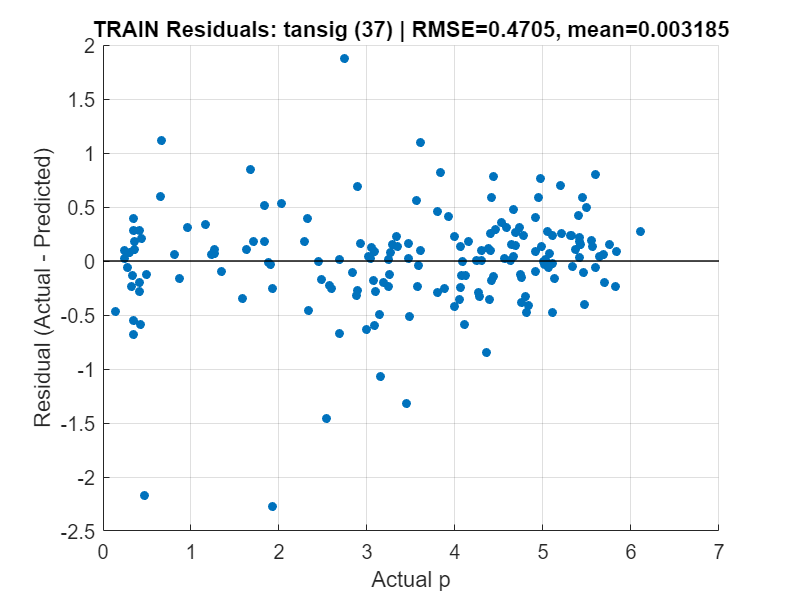

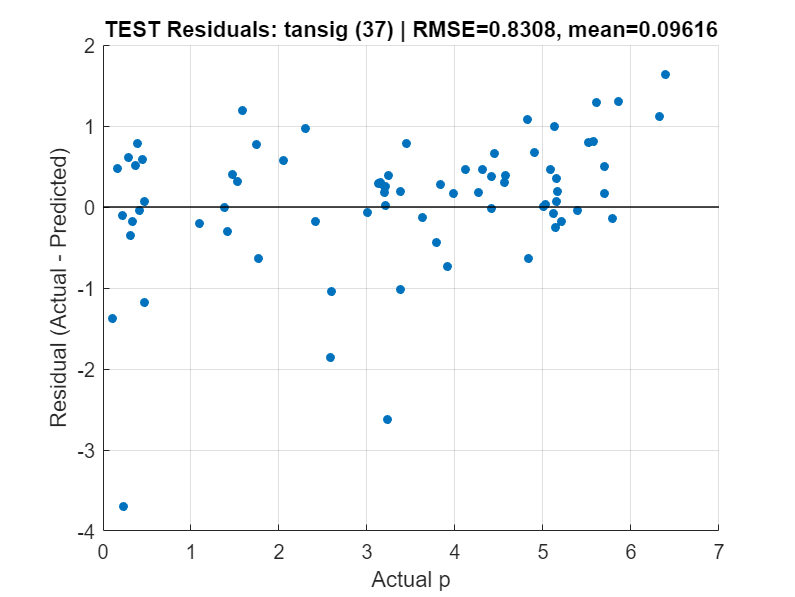


% Save to Excel
writetable(T, 'ann_results_all_1.xlsx', 'Sheet', 'results');

%% Optional: Regression plots for the best case per transfer function
% Pick best by lowest MSE_test within each transfer_fn
Tf = unique(T.transfer_fn);
for k = 1:numel(Tf)
    mask = strcmp(T.transfer_fn, Tf{k});
    Tk = T(mask, :);
    [~, idxBest] = min(Tk.MSE_test);
    bestNeurons = Tk.neurons(idxBest);

    % Re-train that best model to get the final plots
    net = fitnet(bestNeurons);
    net.trainFcn                = 'trainlm';
    net.trainParam.showWindow   = 1;
    net.layers{1}.transferFcn   = Tf{k};
    net.trainParam.epochs       = 1000;
    net.trainParam.lr           = 0.12;
    net.trainParam.mc           = 0.6;
    net.trainParam.min_grad     = 0;
    net.trainParam.mu_max       = 1E100;
    net.divideParam.trainRatio  = 0.75;
    net.divideParam.valRatio    = 0.25;
    net.divideParam.testRatio   = 0.00;

    [net,~]          = train(net, Input_Training', Output_Training');
    ytr_pred         = net(Input_Training')';
    yte_pred         = net(Input_Testing')';

    figure('Name', sprintf('Regression - %s (%d neurons) - TRAIN', Tf{k}, bestNeurons));
    plotregression(Output_Training, ytr_pred, sprintf('TRAIN - %s (%d)', Tf{k}, bestNeurons));
    xlabel('Actual p'); ylabel('Predicted p');

    figure('Name', sprintf('Regression - %s (%d neurons) - TEST', Tf{k}, bestNeurons));
    plotregression(Output_Testing, yte_pred, sprintf('TEST - %s (%d)', Tf{k}, bestNeurons));
    xlabel('Actual p'); ylabel('Predicted p');

     % Residuals
    res_tr = Output_Training - ytr_pred;
    res_te = Output_Testing  - yte_pred;

    % Quick stats (optional)
    rmse_tr = sqrt(mean(res_tr.^2));
    rmse_te = sqrt(mean(res_te.^2));
    mu_tr   = mean(res_tr);
    mu_te   = mean(res_te);

    % --- TRAIN residuals ---
    figure('Name', sprintf('Residuals vs Actual - TRAIN - %s (%d)', Tf{k}, bestNeurons));
    scatter(Output_Training, res_tr, 20, 'filled'); grid on;
    hold on; yline(0,'k-','LineWidth',1); hold off;
    xlabel('Actual p');
    ylabel('Residual (Actual - Predicted)');
    title(sprintf('TRAIN Residuals: %s (%d) | RMSE=%.4g, mean=%.4g', Tf{k}, bestNeurons, rmse_tr, mu_tr));

    % --- TEST residuals ---
    figure('Name', sprintf('Residuals vs Actual - TEST - %s (%d)', Tf{k}, bestNeurons));
    scatter(Output_Testing, res_te, 20, 'filled'); grid on;
    hold on; yline(0,'k-','LineWidth',1); hold off;
    xlabel('Actual p');
    ylabel('Residual (Actual - Predicted)');
    title(sprintf('TEST Residuals: %s (%d) | RMSE=%.4g, mean=%.4g', Tf{k}, bestNeurons, rmse_te, mu_te));
    tag = sprintf('%s_%d', Tf{k}, bestNeurons);

% Regression data tables
TrainReg = table(Output_Training, ytr_pred, ...
    'VariableNames', {'Actual_p','Predicted_p'});

TestReg  = table(Output_Testing,  yte_pred, ...
    'VariableNames', {'Actual_p','Predicted_p'});

% Residual data tables
TrainRes = table(Output_Training, res_tr, ...
    'VariableNames', {'Actual_p','Residual_ActualMinusPred'});

TestRes  = table(Output_Testing,  res_te, ...
    'VariableNames', {'Actual_p','Residual_ActualMinusPred'});

% Optional: compute best-fit line (Pred = a*Actual + b) for Excel
p_tr = polyfit(Output_Training, ytr_pred, 1);
p_te = polyfit(Output_Testing,  yte_pred, 1);

FitLines = table( ...
    p_tr(1), p_tr(2), p_te(1), p_te(2), ...
    'VariableNames', {'Train_slope','Train_intercept','Test_slope','Test_intercept'});

% Optional: 1:1 line endpoints (Excel can plot as a line)
mn = min([Output_Training; Output_Testing; ytr_pred; yte_pred]);
mx = max([Output_Training; Output_Testing; ytr_pred; yte_pred]);
OneToOne = table([mn; mx],[mn; mx], 'VariableNames', {'x','y'});

% Write to one Excel file, multiple sheets
outXlsx = 'plot_data_for_excel.xlsx';
writetable(TrainReg, outXlsx, 'Sheet', ['TrainReg_' tag]);
writetable(TestReg,  outXlsx, 'Sheet', ['TestReg_'  tag]);
writetable(TrainRes, outXlsx, 'Sheet', ['TrainRes_' tag]);
writetable(TestRes,  outXlsx, 'Sheet', ['TestRes_'  tag]);
writetable(FitLines, outXlsx, 'Sheet', ['Fit_'      tag]);
writetable(OneToOne, outXlsx, 'Sheet', ['OneToOne_' tag]);

% Also save CSVs if you prefer
writetable(TrainReg, ['TrainReg_' tag '.csv']);
writetable(TestReg,  ['TestReg_'  tag '.csv']);
writetable(TrainRes, ['TrainRes_' tag '.csv']);
writetable(TestRes,  ['TestRes_'  tag '.csv']);
end